# Inverted Pendulum Dynamics

m = 1;
M = 5;
L = 2;
g = -10;
d = 1;

b = 1; % pendulum up (b=1)

A = [0 1 0 0;
    0 -d/M b*m*g/M 0;
    0 0 0 1;
    0 -b*d/(M*L) -b*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; b*1/(M*L)];

dt = 0.02;
% Create state space model
sys = ss(A,B,[],[]);
% Convert to discrete, where dt is your discrete time-step (in seconds)
% d_sys = c2d(sys,dt);

[Ad, Bd] = LTI_translation(A,B,dt);

# Timing Parameters

dt = 0.02;

# Simulation Settings

x0 = [-1; 0; pi+.1; 0];  % initial condition
xr = [1; 0; pi; 0];      % reference position

# Recovery

k = 10;
initial_set_lo = x0 - 0.1;
initial_set_up = x0 + 0.1;
target_set_lo = xr - 0.1;
target_set_up = xr + 0.1;

utemp = recovery_control(Ad, Bd, k, initial_set_lo, initial_set_up, target_set_lo, target_set_up);

Optimal solution found.



result =    -1.1000
   -0.1000
    3.1416
   -0.1000
   -1.1040
   -0.2996
    3.1430
    0.2401
   -1.1119
   -0.4952


u = utemp((length(utemp)-k):end)

u =     3.4169
  -18.6744
  -17.8470
  -23.4656
  -23.4169
  -21.3256
  -22.1530
  -16.5344
  -16.5831
  -20.0000


# Simulator 

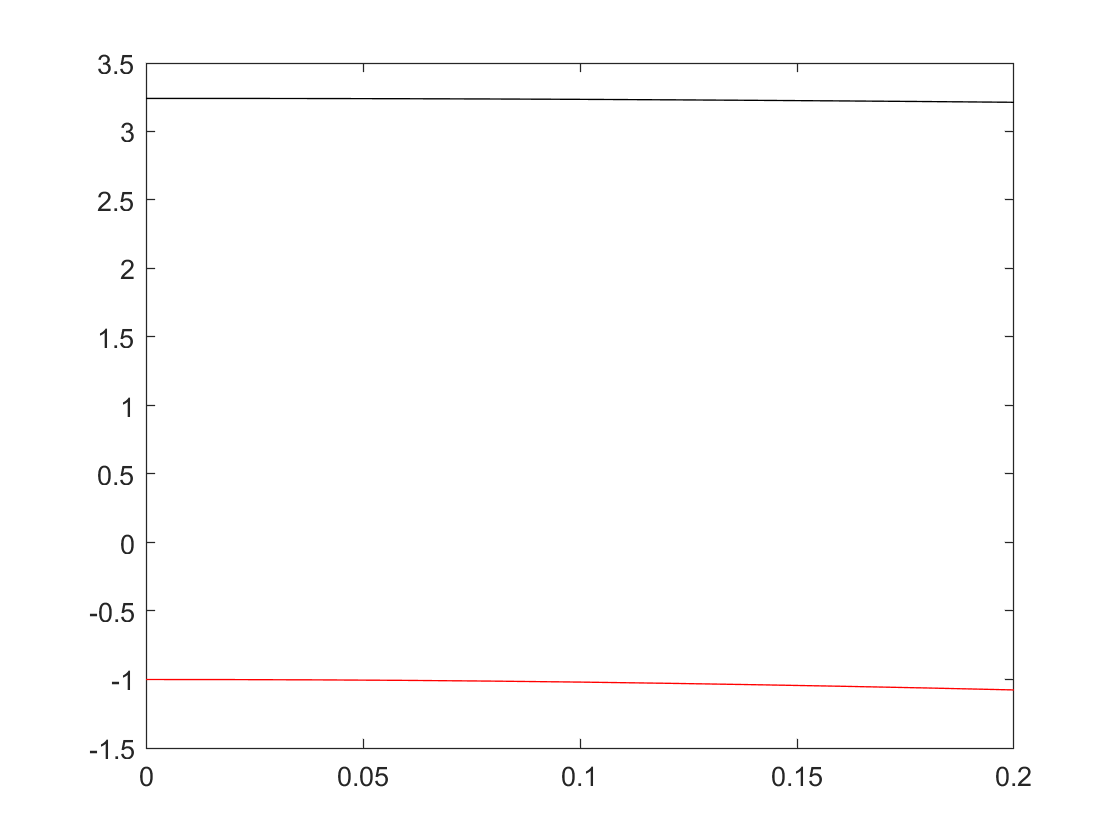

t_span = 0:0.02:k*dt;
x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;

for i = 2:(length(t_span))
    [t,xtemp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,u(i,1)),(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,x(:,1),'r',t_span,x(:,3),'k')